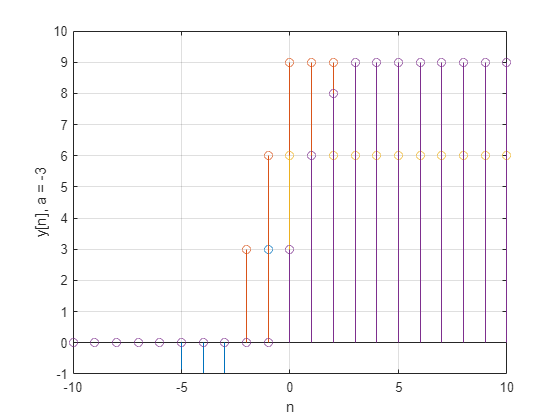

% x[n]
n = -10:10;
x = (n>=-5 & n<=-1).*(n+4) + (n>-1 & n<2).*3 + (n>=2 & n<=5).*(7-2*n);

% ha[n]
a_values = [8, 2, 0, -3];
ha = zeros(size(n));
for a = a_values
    ha = (n>=0 & n<=a) + (n<=0 & n>=a);
    y = zeros(size(n));
    for i = 1:length(n)
        k = n(i) - (a+1):n(i);
        xk = x(max(1,length(n)-i+1):min(length(n),2*length(n)-i));
        hak = ha(max(1,length(n)-i+1):min(length(n),2*length(n)-i));
        y(i) = sum(xk.*hak);
    end
    stem(n, y)
    xlabel('n')
    ylabel(['y[n], a = ', num2str(a)])
    ylim([min(y)-1, max(y)+1])
    grid on
    hold on
end
hold off